clearvars

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

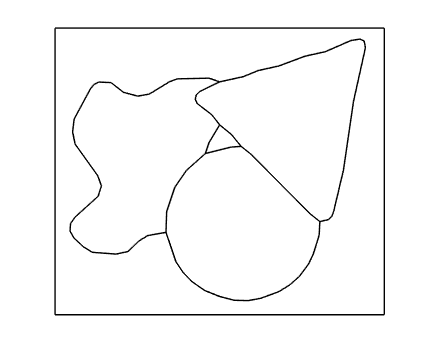

im = imread("Shape.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end

% image to polygon boundary
boundsRaw = im2Bounds( im );
boundsCtrlP = getCtrlPnts( boundsRaw, false, size(im) );

% smooth boundary
boundsSmooth = smoothBounds( boundsCtrlP, 0.5, -0.5, 100, 0, 0 );

% simplify polygon boundary
boundsSimplified = simplifyBounds( boundsSmooth, 0.3, 0 );
boundsSimplified = delZeroAreaPoly( boundsSimplified );

% clear up redundant vertices
% only control points and turning points will remain
boundsClear = getCtrlPnts( boundsSimplified, false );
boundsClear = simplifyBounds( boundsClear, 0 );

plotBounds( boundsClear );

psCellIm = bound2polyshape(boundsClear);

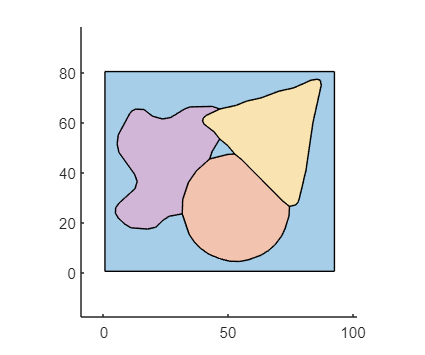

figure
hold on; axis equal;
for i = 1: length(psCellIm)
    plot(psCellIm{i});
end
hold off

## Coordinates of 4 corners

size(im)

ans =     80    92


It means the height and width of the input image is 80 and 92, respectively.

Thus, the x y coordinates of 4 corners in variable psCellIm is 

I forgot why there is 0.5 shifting in x y coordinates since some code in Im2mesh were written many years ago.

Therefore, based on 4 corners, we can know that the mid point of the upper boundary is [ 46.5, 80.5 ], and the mid point of the right boundary is [ 92.5, 40.5 ]. We use them later.

xMidUp = 46.5;
yMidUp = 80.5;
xMidRight = 92.5;
yMidRight = 40.5;

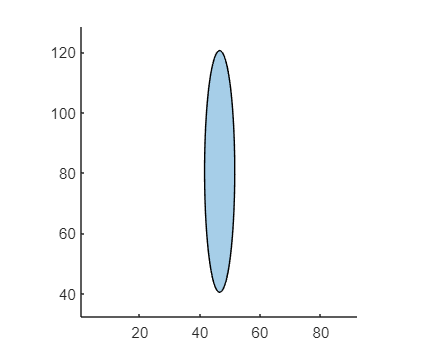

t = 0.05:0.03:2*pi;
x1 = xMidUp + 5*cos(t);
y1 = yMidUp + 40*sin(t);
psCircle = polyshape(x1,y1);
plot( psCircle ); axis equal

psCellCrop = psCellIm;
for i = 1: length(psCellCrop)
    psCellCrop{i} = subtract( psCellCrop{i}, psCircle );
end

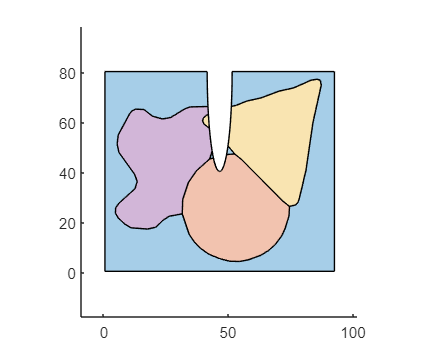

figure
hold on; axis equal;
for i = 1: length(psCellCrop)
    plot(psCellCrop{i});
end
hold off

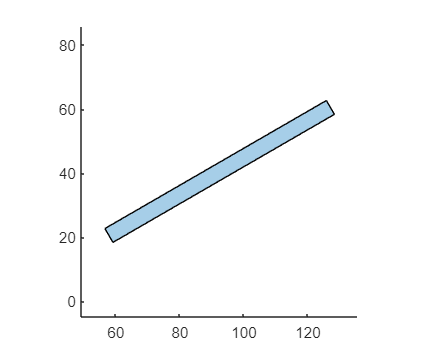

vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);
psRod = scale( psUnitSq, [80, 5]);

[xc,yc] = centroid(psRod);
vec = [ xMidRight - xc, yMidRight - yc];
psRod = translate( psRod, vec );

[xc,yc] = centroid(psRod);
psRod = rotate( psRod, 30, [xc,yc] );

plot( psRod ); axis equal

for i = 1: length(psCellCrop)
    psCellCrop{i} = subtract( psCellCrop{i}, psRod );
end

psCellCrop{end+1} = psRod;

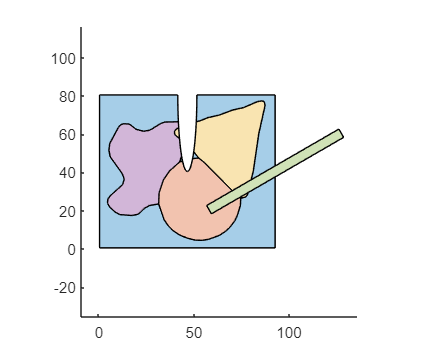

figure
hold on; axis equal;
for i = 1: length(psCellCrop)
    plot(psCellCrop{i});
end
hold off

boundsCrop = polyshape2bound(psCellCrop);

tol_intersect = 1e-6;
boundsCrop = addIntersectPnts( boundsCrop, tol_intersect );

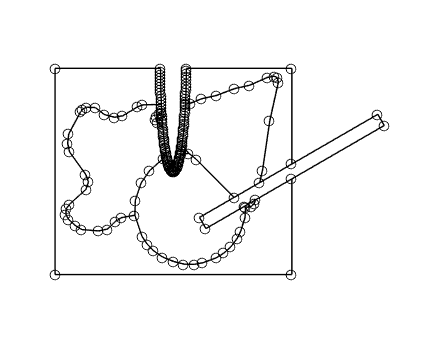

plotBounds( boundsCrop, false, 'ko-' )

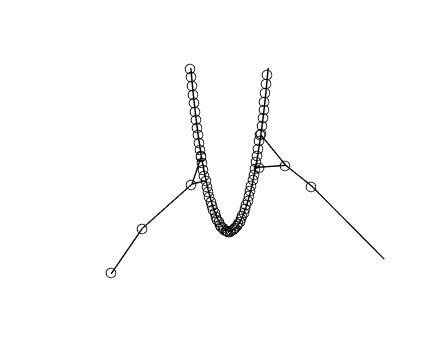

plotBounds( boundsCrop, false, 'ko-' )
xlim([27.9 63.0])
ylim([35.9 57.8])

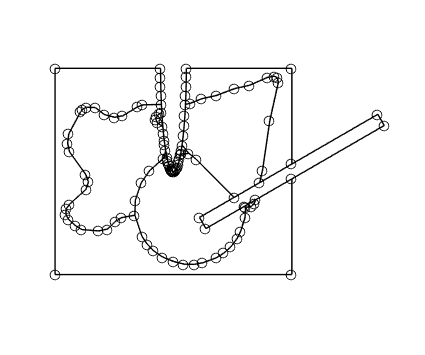

boundsCropCtrlP = getCtrlPnts( boundsCrop, false );
boundsCropSimplified = simplifyBounds( boundsCropCtrlP, 0.02, 0 );

plotBounds( boundsCropSimplified, false, 'ko-' );

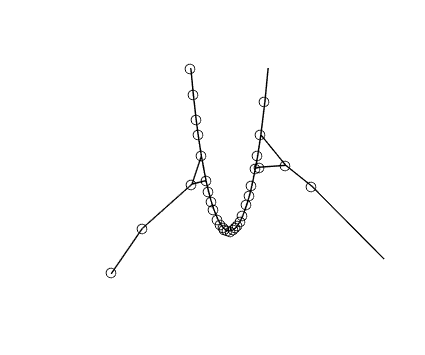

plotBounds( boundsCropSimplified, false, 'ko-' );
xlim([27.9 63.0])
ylim([35.9 57.8])

[ poly_node, poly_edge ] = getPolyNodeEdge( boundsCropSimplified );

hmax = 500; 
mesh_kind = 'delaunay';
grad_limit = 0.25;
[ vert,tria,tnum,vert2,tria2 ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                163                188
         10                193                413
         15                196                485


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          9                304                188
         10                304                447
         20                312               1780
         22                312               1796


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                481               1776
     

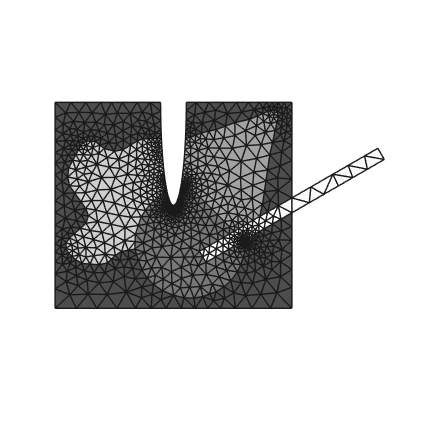

plotMeshes(vert,tria,tnum);

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo